# The Training Unit 2: NEDC Simulation

Fink Lucas / Teichtmeister Marcus, 08.10.2025

## MATLAB Setup

clear
clc

LaTex-Interpreter als Standard für Grafiken setzen

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Schriftgröße für Grafiken setzen

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Verzeichnis wechseln (in Verzeichnis des Live-Skripts)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Loading and processing of existing data

Storing the parameters of the vehicle under investigation

VEHICLE_PARAMETER.VEHICLE_WEIGHT.data        = struct('value', 1250, 'unit', 'kg');
VEHICLE_PARAMETER.E_MOTOR_POWER.data         = struct('value', 60,   'unit', 'kW');
VEHICLE_PARAMETER.BATTERY_CAPACITY.data      = struct('value', 22,   'unit', 'kWh');
VEHICLE_PARAMETER.TRANSMISSION_EFFIENCY.data = struct('value', 96,   'unit', '%');
VEHICLE_PARAMETER.ENGINE_EFFIENCY.data       = struct('value', 94,   'unit', '%');
VEHICLE_PARAMETER.INVERTER_EFFIENCY.data     = struct('value', 97,   'unit', '%');
VEHICLE_PARAMETER.BATTERY_EFFIENCY.data      = struct('value', 90,   'unit', '%');
VEHICLE_PARAMETER.CHARGER_EFFIENCY.data      = struct('value', 94,   'unit', '%');

Next, the collected data "MotorSpeed", "Distance" and "VehicleSpeed" will be read out from the Data.xls File. The data is merged into a table with 3 columns. This is handled by the MATLAB function "importExcelData" which gets the filename as a parameter and returns the extracted data table.

The displayed size of the table is: 2401x3

filename_data = 'Data.xls';
dataTable = importExcelData(filename_data)

dataTable = 2401×3 table
    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]
    _________________    ___________    __________________
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                

Furthermore, a second MATLAB function "importTorqueData" is implemented which stores the torque data in the already existing data table and also includes the sampling time as the first column in the table.

The object **Motor_Torque i**ncludes 2401 data points of motor torque values over time. The dataset provides both the torque data and the corresponding time vector, as well as additional metadata for time, data, and quality. The datapoints of the time vector suggests that the data was recorded with consistent sampling. The metadata also indicates that NaN values are treated as missing data.

filename_torque = 'Torque.mat';
dataTable = importTorqueData(filename_torque, dataTable)

dataTable = 2401×5 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]
    ________________    _________________    ___________    __________________    __________
            0                   0                 0                 0                 0     
          0.5                   0                 0                 0                 0     
            1                   0                 0                 0                 0     
          1.5                   0                 0                 0                 0     
            2                   0                 0                 0                 0     
          2.5                   0                 0                 0                 0     
            3                   0                 0          

The imported torque time series and other artifacts are removed from the workspace.

clearvars -except dataTable VEHICLE_PARAMETER;

### Presenting the results

In the next four plots, the variables MotorSpeed, Distance, VehicleSpeed and and Torque are plotted over the sampled time period.

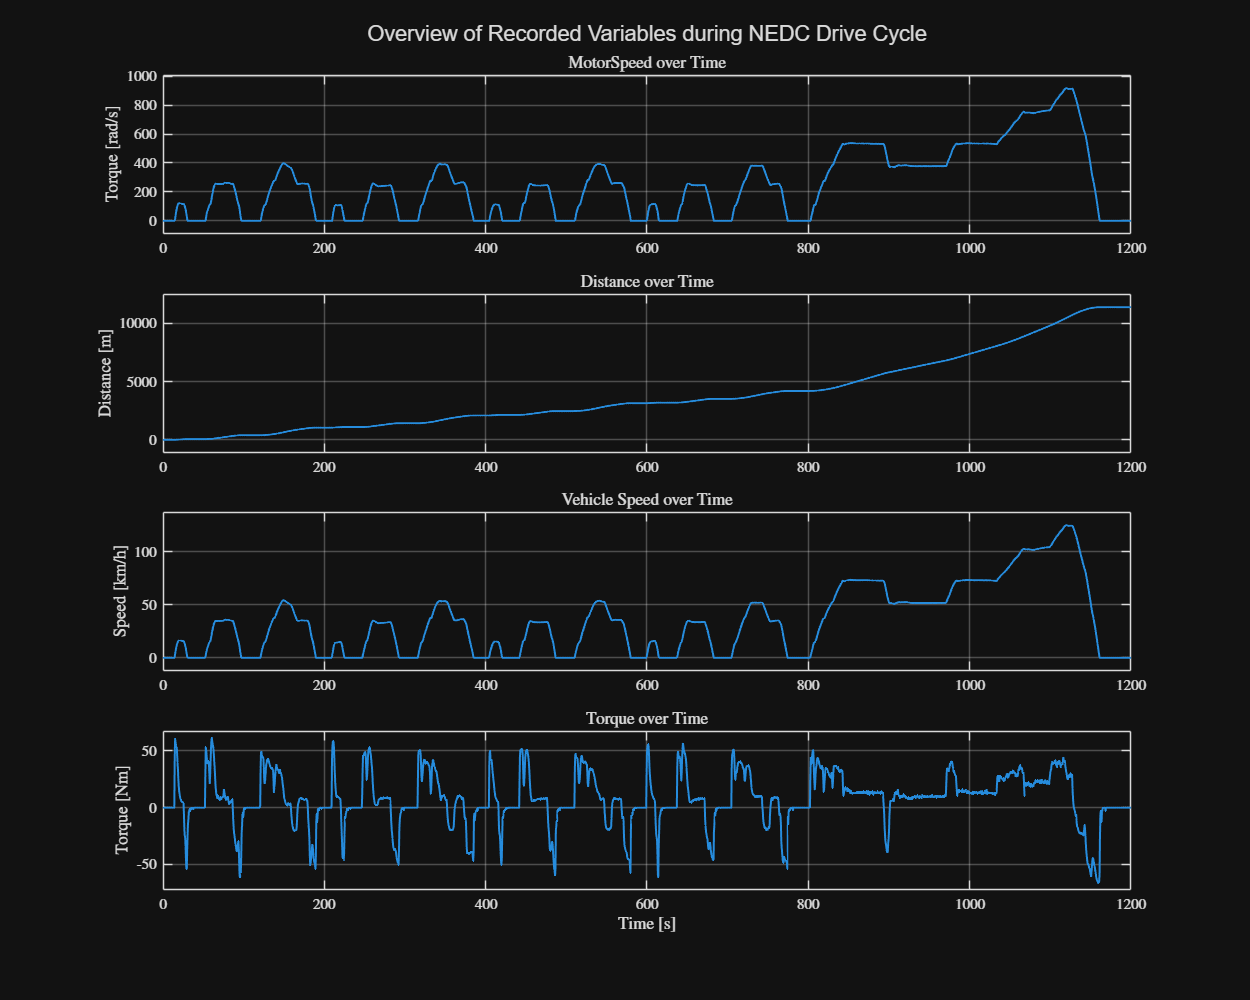

time = dataTable{:,1};              
motor_speed = dataTable{:,2};             
distance = dataTable{:,3};              
vehicle_speed = dataTable{:,4};             
torque = dataTable{:,5};              

figure('Position', [100, 100, 1000, 800])
tiledlayout(4, 1)    

% 1. Plot: MotorSpeed
nexttile
plot(time, motor_speed, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(motor_speed)-0.1*max(motor_speed), max(motor_speed)+0.1*max(motor_speed)])
title('MotorSpeed over Time')
ylabel('Torque [rad/s]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

% 2. Plot: Distance
nexttile
plot(time, distance, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(distance)-0.1*max(distance), max(distance)+0.1*max(distance)])
title('Distance over Time')
ylabel('Distance [m]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

% 3. Plot VehicleSpeed
nexttile
plot(time, vehicle_speed, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(vehicle_speed)-0.1*max(vehicle_speed), max(vehicle_speed)+0.1*max(vehicle_speed)])
title('Vehicle Speed over Time')
ylabel('Speed [km/h]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

% 4.Plot: Torque
nexttile
plot(time, torque, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(torque)-0.1*max(torque), max(torque)+0.1*max(torque)])
title('Torque over Time')
xlabel('Time [s]')
ylabel('Torque [Nm]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

clearvars -except dataTable VEHICLE_PARAMETER;
sgtitle('Overview of Recorded Variables during NEDC Drive Cycle')

## Performing Calculations / Conversions on the data table

The motor speed is converted from rad/s to rpm and stored in a separate column in the data table.

Motor_RPM = 30/pi .* dataTable.("MotorSpeed[rad/s]");
dataTable = [dataTable, table(Motor_RPM,VariableNames="MotorSpeed[rpm]")]

dataTable = 2401×6 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]
    ________________    _________________    ___________    __________________    __________    _______________
            0                   0                 0                 0                 0                0       
          0.5                   0                 0                 0                 0                0       
            1                   0                 0                 0                 0                0       
          1.5                   0                 0                 0                 0                0       
            2                   0                 0                 0                 0            

Next,  the mean vehicle speed in km/h is calculated and stored in a new structure. 

AVG_VELOCITY = 1/dataTable.('sampling_time[s]')(2401) * dataTable.("Distance[m]")(2401) * 3.6

AVG_VELOCITY =     34.1392e+000

VEHICLE_CHAR.MEAN_VEL.data        = struct('value', AVG_VELOCITY, 'unit', 'km/h');

The mechanical power demanded by the vehicle can be calculated with the formula: $P_{\textrm{mech}} =T\cdot \omega$. It is then also stored in the data table. 

P_mech = dataTable.("MotorSpeed[rad/s]") .* dataTable.('Torque[Nm]');
dataTable = [dataTable, table(P_mech, VariableNames="P_mech[W]")]

dataTable = 2401×7 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]    P_mech[W]
    ________________    _________________    ___________    __________________    __________    _______________    _________
            0                   0                 0                 0                 0                0               0    
          0.5                   0                 0                 0                 0                0               0    
            1                   0                 0                 0                 0                0               0    
          1.5                   0                 0                 0                 0                0        

The motor has a power of 60 kW (VEHICLE_PARAMETER.E_MOTOR_POWER.data), whereas the maximum calculated mechanical power is 39 kW. Thus, the motor is sufficiently.

P_mech_max = max(dataTable.('P_mech[W]'))

P_mech_max =     39.5518e+003

VEHICLE_PARAMETER.E_MOTOR_POWER.data

ans = struct with fields:
    value: 60.0000e+000
     unit: 'kW'

E_inst = 1 / 2 .* dataTable.("P_mech[W]");
dataTable = [dataTable, table(E_inst, VariableNames="E_inst[J]")]

dataTable = 2401×8 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]    P_mech[W]    E_inst[J]
    ________________    _________________    ___________    __________________    __________    _______________    _________    _________
            0                   0                 0                 0                 0                0               0            0    
          0.5                   0                 0                 0                 0                0               0            0    
            1                   0                 0                 0                 0                0               0            0    
          1.5

### Presenting the results

In the first plot, the vehicle speed, motor speed and the average vehicle velocity is displayed. 

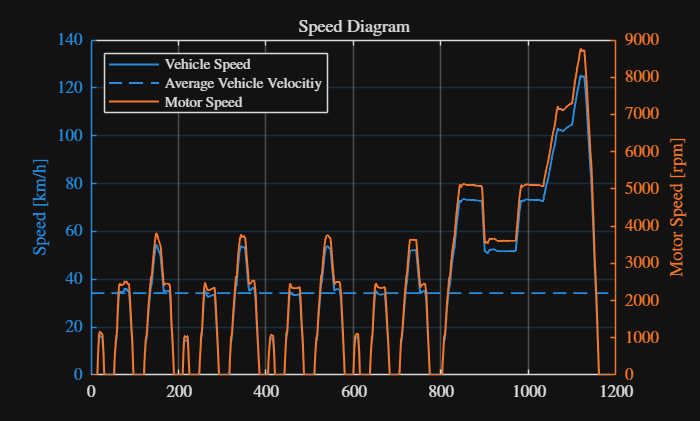

time = dataTable{:, "sampling_time[s]"};     
vehicle_speed = dataTable{:,"VehicleSpeed[km/h]"};
motor_RPM = dataTable{:, "MotorSpeed[rpm]"};

figure
tiledlayout(1, 1)    

% Vehicle Speed, Mean-Vehicle Speed, Motor Speed
nexttile
yyaxis left
plot(time, vehicle_speed, 'LineWidth', 1.2)
hold on
plot(time, AVG_VELOCITY*ones(size(time)), 'LineWidth', 1.2)
grid on
ylabel('Speed [km/h]')
yyaxis right
plot(time, motor_RPM, 'LineWidth', 1.2)
grid on
ylabel('Motor Speed [rpm]');

title('Speed Diagram')
legend('Vehicle Speed', 'Average Vehicle Velocitiy', 'Motor Speed', 'Location','northwest')

In the second plot, the mechanical power is plotted over time. Additionally, a dashed line indicates the maximum available power of the engine.

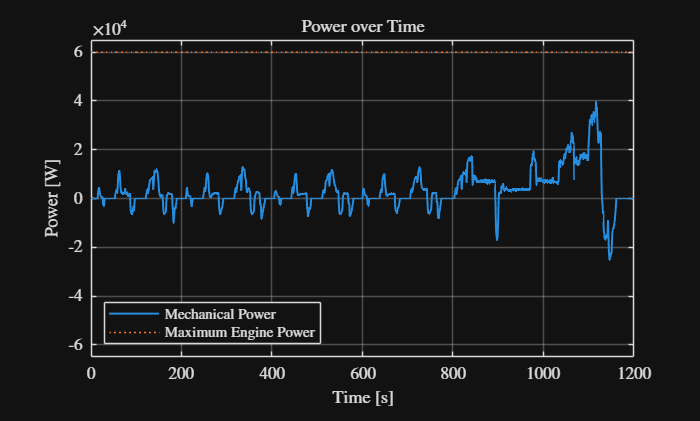

Powermech = dataTable{:,"P_mech[W]"};
Powerenginemax = VEHICLE_PARAMETER.E_MOTOR_POWER.data.value * 1000;
Powerenginemax_vec = ones(size(time)) * Powerenginemax;


figure
tiledlayout(1, 1)    

% Mechanical Power
nexttile
plot(time, Powermech, 'LineWidth', 1.2)
line(time, Powerenginemax_vec, 'LineStyle',':')
grid on
xlabel('Time [s]')
ylabel('Power [W]')
title('Power over Time')
ylim([-6.5e4 6.5e4])
legend('Mechanical Power', 'Maximum Engine Power', 'Location','southwest')

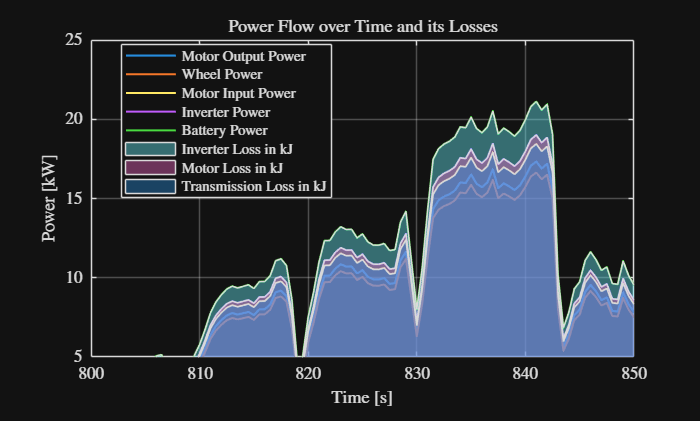

% Time and Mechanical Power
time = dataTable{:, "sampling_time[s]"};             
P_Motor_out = dataTable{:,"P_mech[W]"};
E_Motor_out = dataTable{:,"E_inst[J]"};

% Efficiencies
eta_trans     = double(VEHICLE_PARAMETER.TRANSMISSION_EFFIENCY.data.value)/100;
eta_motor     = double(VEHICLE_PARAMETER.ENGINE_EFFIENCY.data.value)/100;
eta_inverter  = double(VEHICLE_PARAMETER.INVERTER_EFFIENCY.data.value)/100;
eta_battery   = double(VEHICLE_PARAMETER.BATTERY_EFFIENCY.data.value)/100;

%% Power Vector for each step
P_Wheel    = zeros(size(P_Motor_out));
P_Motor_in = zeros(size(P_Motor_out));
P_Inverter = zeros(size(P_Motor_out));
P_Battery  = zeros(size(P_Motor_out));

E_Wheel    = zeros(size(E_Motor_out));
E_Motor_in = zeros(size(E_Motor_out));
E_Inverter = zeros(size(E_Motor_out));
E_Battery  = zeros(size(E_Motor_out));

% Power Vector for each step when Power is used, same with the Energy
idx_pos = P_Motor_out >= 0;
P_Wheel(idx_pos)    =  P_Motor_out(idx_pos) .* eta_trans;
P_Motor_in(idx_pos) =  P_Motor_out(idx_pos) ./ eta_motor;
P_Inverter(idx_pos) =  P_Motor_in(idx_pos) ./ eta_inverter;
P_Battery(idx_pos)  =  P_Inverter(idx_pos) ./ eta_battery;

idx_pos = E_Motor_out >= 0;
E_Wheel(idx_pos)    =  E_Motor_out(idx_pos) .* eta_trans;
E_Motor_in(idx_pos) =  E_Motor_out(idx_pos) ./ eta_motor;
E_Inverter(idx_pos) =  E_Motor_in(idx_pos) ./ eta_inverter;
E_Battery(idx_pos)  =  E_Inverter(idx_pos) ./ eta_battery;

% Power Vector for each step when Power is recuperated, same with Energy
idx_neg = P_Motor_out < 0;
P_Wheel(idx_neg)    =  P_Motor_out(idx_neg) ./ eta_trans;
P_Motor_in(idx_neg) =  P_Motor_out(idx_neg) .* eta_motor;
P_Inverter(idx_neg) =  P_Motor_in(idx_neg) .* eta_inverter;
P_Battery(idx_neg)  =  P_Inverter(idx_neg) .* eta_battery;

idx_neg = E_Motor_out < 0;
E_Wheel(idx_neg)    =  E_Motor_out(idx_neg) ./ eta_trans;
E_Motor_in(idx_neg) =  E_Motor_out(idx_neg) .* eta_motor;
E_Inverter(idx_neg) =  E_Motor_in(idx_neg) .* eta_inverter;
E_Battery(idx_neg)  =  E_Inverter(idx_neg) .* eta_battery;

% Losses
P_Loss_Inverter = P_Battery - P_Inverter;
P_Loss_Motor = P_Inverter - P_Motor_in;
P_Loss_Trans = P_Motor_in - P_Wheel;

% Total Energy Loss
E_Loss_Inverter = 0.5 * sum(P_Loss_Inverter) / 2401;
E_Loss_Motor = 0.5 * sum(P_Loss_Motor) / 2401;
E_Loss_Trans = 0.5 * sum(P_Loss_Trans) / 2401;

%% Plot
figure
tiledlayout(1, 1)
nexttile

% Power of each step in kW
plot(time, P_Motor_out/1000, 'LineWidth', 1.3, 'DisplayName','Motor Output Power');
hold on
plot(time, P_Wheel/1000, 'LineWidth', 1.2, 'DisplayName','Wheel Power');
plot(time, P_Motor_in/1000, 'LineWidth', 1.2, 'DisplayName','Motor Input Power');
plot(time, P_Inverter/1000, 'LineWidth', 1.2, 'DisplayName','Inverter Power');
plot(time, P_Battery/1000, 'LineWidth', 1.2, 'DisplayName','Battery Power');
% Losses of each step in kJ
area(time, (P_Inverter+P_Loss_Inverter)/1000, 'FaceAlpha', 0.4, 'DisplayName', 'Inverter Loss in kJ');
area(time, (P_Motor_in+P_Loss_Motor)/1000, 'FaceAlpha', 0.4, 'DisplayName', 'Motor Loss in kJ');
area(time, (P_Wheel+P_Loss_Trans)/1000, 'FaceAlpha', 0.4, 'DisplayName', 'Transmission Loss in kJ');


grid on
xlabel('Time [s]')
ylabel('Power [kW]')
title('Power Flow over Time and its Losses')
legend('Location','best')
ylim([5 25])
xlim([800 850])

Time frame between 800 and 850 seconds is used, to better visualize the different powers and its losses.

dataTable = [dataTable, table(P_Battery, VariableNames="P_Battery[W]"), table(P_Inverter, VariableNames="P_Inverter[W]"), table(P_Wheel, VariableNames="P_Wheel[W]"), table(P_Motor_in, VariableNames="P_Motor_in[W]"), table(E_Battery, VariableNames="E_Battery[J]"), table(E_Inverter, VariableNames="E_Inverter[J]"), table(E_Wheel, VariableNames="E_Wheel[J]"), table(E_Motor_in, VariableNames="E_Motor_in[J]")]

dataTable = 2401×16 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]    P_mech[W]    E_inst[J]    P_Battery[W]    P_Inverter[W]    P_Wheel[W]    P_Motor_in[W]    E_Battery[J]    E_Inverter[J]    E_Wheel[J]    E_Motor_in[J]
    ________________    _________________    ___________    __________________    __________    _______________    _________    _________    ____________    _____________    __________    _____________    ____________

VEHICLE_CHAR.INVERTER_LOSS.data        = struct('value', E_Loss_Inverter, 'unit', 'J');
VEHICLE_CHAR.MOTOR_LOSS.data        = struct('value', E_Loss_Motor, 'unit', 'J');
VEHICLE_CHAR.TRANSMISSION_LOSS.data        = struct('value', E_Loss_Trans, 'unit', 'J');

clearvars -except dataTable VEHICLE_PARAMETER VEHICLE_CHAR;

%%%